# Tarea 1

# Control Robusto y Análisis  de Desempeño  : Vehículo Aéreo no Tripulado. 

## Daniel Melo Avila

## Dylan Ortiz Mayorga

## Juan Pablo Vallejo Montañez

### Universidad Nacional de Colombia 

#### **1.Consideraciónes Inciales**

clc 
clear
load("modelo_lin.mat");

El objetivo es diseñar controladores PID y Hinf para una planta correspondiente a una aeronave tipo UAV. Se parte de un modelo nominal  lineal acoplado.

Para cada uno de los ejes del UAV se tiene la siguiente nomenclatura

**2.Eje Longitudinal - Control PI+D**

%Nomnclatura variables Eje Longitudinal 
% Inputs (1) Elevator, (2) Throttle
% Outputs (3) q-velocidad pitch ,(4) theta-angulo pitch
longmod

longmod =
 
  A = 
                   u           w           q       theta          Ze       omega
   u         -0.5961      0.8011      -0.871      -9.791   5.053e-05     0.01263
   w         -0.7454      -7.581       15.72     -0.5272  -0.0009384           0
   q           1.042      -7.427      -15.85           0  -8.001e-16    -0.01318
   theta           0           0           1           0           0           0
   Ze       -0.05377      0.9986           0         -17           0           0
   omega       135.8       7.315           0           0    -0.08268      -5.919
 
  B = 
          elevator  throttle
   u        0.4681         0
   w        -2.711         0
   q        -134.1         0
   theta         0         0
   Ze            0         0
   omega         0      2506
 
  C = 
                   u           w           q       theta          Ze       omega
   V          0.9986     0.05377           0           0           0           0
   alpha   -0.003163     0.0587

Gel_pit=tf(longmod(4,1))

Gel_pit =
 
  From input "elevator" to output "theta":
          -134.1 s^4 - 1869 s^3 - 6807 s^2 - 2268 s - 0.07966
  --------------------------------------------------------------------
  s^6 + 29.95 s^5 + 392.9 s^4 + 1609 s^3 + 637.7 s^2 + 642 s + 0.07726
 
Continuous-time transfer function.



Gel_q=tf(longmod(3,1))

Gel_q =
 
  From input "elevator" to output "q":
  -134.1 s^5 - 1869 s^4 - 6807 s^3 - 2268 s^2 - 0.07966 s - 1.917e-17
  --------------------------------------------------------------------
  s^6 + 29.95 s^5 + 392.9 s^4 + 1609 s^3 + 637.7 s^2 + 642 s + 0.07726
 
Continuous-time transfer function.



el_q=ss(Gel_q);

Se obtiene la respuesta al impulso del ángulo de Pitch y su velocidad respecto al elevador con el fin de caracterizar el sistema y conocer sus propiedades.

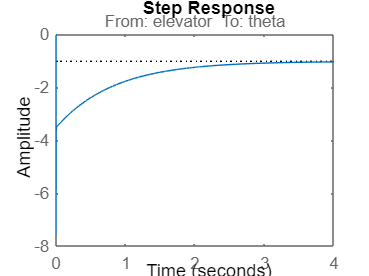

%Pitch
step(Gel_pit)

stepinfo(Gel_pit)

ans = struct with fields:
         RiseTime: 0.2192
    TransientTime: 2.4544e+04
     SettlingTime: 3.9865e+04
      SettlingMin: -7.5487
      SettlingMax: -1.0418
        Overshoot: 632.1713
       Undershoot: 0
             Peak: 7.5487
         PeakTime: 3.0609


damp(Gel_pit)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.20e-04                 1.00e+00       1.20e-04         8.31e+03    
 -1.60e-01 + 6.40e-01i     2.42e-01       6.60e-01         6.26e+00    
 -1.60e-01 - 6.40e-01i     2.42e-01       6.60e-01         6.26e+00    
 -6.20e+00                 1.00e+00       6.20e+00         1.61e-01    
 -1.17e+01 + 1.00e+01i     7.60e-01       1.54e+01         8.54e-02    
 -1.17e+01 - 1.00e+01i     7.60e-01       1.54e+01         8.54e-02    


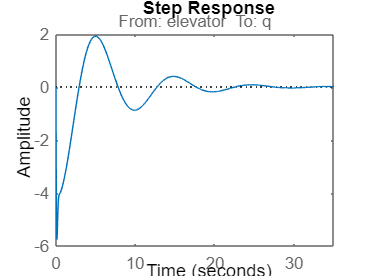

%Pitch Rate
step(Gel_q)

stepinfo(Gel_q)

ans = struct with fields:
         RiseTime: 1.7347e-18
    TransientTime: 21.1506
     SettlingTime: NaN
      SettlingMin: -5.7569
      SettlingMax: 1.9145
        Overshoot: 2.3197e+18
       Undershoot: 7.7143e+17
             Peak: 5.7569
         PeakTime: 0.1179


damp(Gel_q)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.20e-04                 1.00e+00       1.20e-04         8.31e+03    
 -1.60e-01 + 6.40e-01i     2.42e-01       6.60e-01         6.26e+00    
 -1.60e-01 - 6.40e-01i     2.42e-01       6.60e-01         6.26e+00    
 -6.20e+00                 1.00e+00       6.20e+00         1.61e-01    
 -1.17e+01 + 1.00e+01i     7.60e-01       1.54e+01         8.54e-02    
 -1.17e+01 - 1.00e+01i     7.60e-01       1.54e+01         8.54e-02    


**2.1 SAS**

Para diseñar el lazo interno referente al sistema SAS se analiza el lugar de las raices (para ganancias negativas principalemente) de los polos de la función de trasnferencia : 


$$G\left(s\right)=\frac{\dot{\theta} }{\textrm{Elevator}}$$


***Ganancias Positivas***

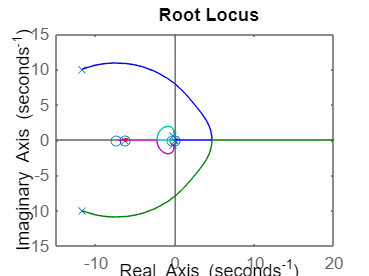

rlocus(Gel_q)

Para ganancias positivas, se puede observar que para valores de K mayores a 0.175 se presenta inestabilidad debido al polo complejo conjugado $-11\ldotp 7\pm 10i$.

En el intervalo $\left\lbrack 0;0\ldotp 175\right\rbrack$, el sistema es estable sin embargo el amortiguamiento del sistema disminuye.

***Ganancias Negativas***

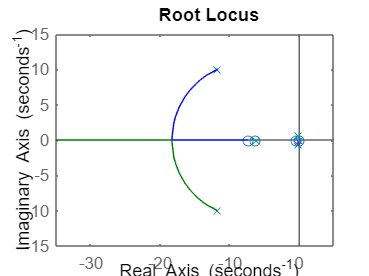

rlocus(-Gel_q)

Para ganacias negativas se evidencia estabilidad para cualquier valor de K, por lo que se selecciona el valor de esta constante como la ganacia necesaria para que el polo menos amortiguado tenga un amortiguamiento equivalente a 1.

Se toma un valor de : 


$$k=-2\ldotp 92$$


kel_q=-2.92;
nd=[1 0];dd=[1];dev=tf(nd,dd)

dev =
 
  s
 
Continuous-time transfer function.



%PropFeedback in PitchRate/Elevator TF 
Gel_qSAS=feedback(Gel_q,kel_q)

Gel_qSAS =
 
  From input "elevator" to output "q":
    -134.1 s^5 - 1869 s^4 - 6807 s^3 - 2268 s^2 - 0.07966 s - 1.917e-17
  ------------------------------------------------------------------------
  s^6 + 421.4 s^5 + 5851 s^4 + 2.149e04 s^3 + 7260 s^2 + 642.2 s + 0.07726
 
Continuous-time transfer function.



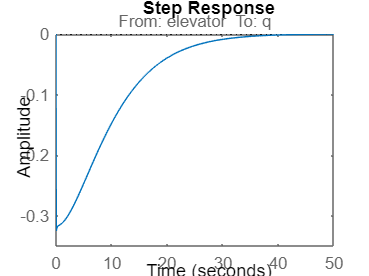

step(Gel_qSAS)

stepinfo(Gel_qSAS)

ans = struct with fields:
         RiseTime: 4.1633e-17
    TransientTime: 31.9013
     SettlingTime: NaN
      SettlingMin: -0.3251
      SettlingMax: 8.0634e-05
        Overshoot: 1.3099e+17
       Undershoot: 3.2491e+13
             Peak: 0.3251
         PeakTime: 0.0541


damp(Gel_qSAS)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -1.20e-04     1.00e+00       1.20e-04         8.30e+03    
 -1.70e-01     1.00e+00       1.70e-01         5.88e+00    
 -1.94e-01     1.00e+00       1.94e-01         5.15e+00    
 -6.23e+00     1.00e+00       6.23e+00         1.60e-01    
 -7.64e+00     1.00e+00       7.64e+00         1.31e-01    
 -4.07e+02     1.00e+00       4.07e+02         2.46e-03    


%DevFeedback in Pitch/Elevator TF
Gel_pitSAS=feedback(Gel_pit,kel_q*dev)

Gel_pitSAS =
 
  From input "elevator" to output "theta":
            -134.1 s^4 - 1869 s^3 - 6807 s^2 - 2268 s - 0.07966
  ------------------------------------------------------------------------
  s^6 + 421.4 s^5 + 5851 s^4 + 2.149e04 s^3 + 7260 s^2 + 642.2 s + 0.07726
 
Continuous-time transfer function.



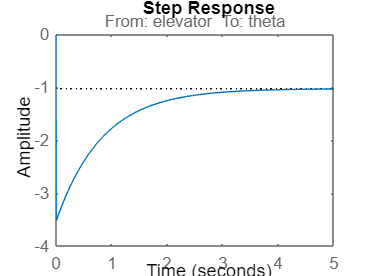

step(Gel_pitSAS)

stepinfo(Gel_pitSAS)

ans = struct with fields:
         RiseTime: 2.7053
    TransientTime: 3.2531e+04
     SettlingTime: 3.9850e+04
      SettlingMin: -3.5210
      SettlingMax: -0.9353
        Overshoot: 241.5094
       Undershoot: 0
             Peak: 3.5210
         PeakTime: 51.9888


damp(Gel_pitSAS)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -1.20e-04     1.00e+00       1.20e-04         8.30e+03    
 -1.70e-01     1.00e+00       1.70e-01         5.88e+00    
 -1.94e-01     1.00e+00       1.94e-01         5.15e+00    
 -6.23e+00     1.00e+00       6.23e+00         1.60e-01    
 -7.64e+00     1.00e+00       7.64e+00         1.31e-01    
 -4.07e+02     1.00e+00       4.07e+02         2.46e-03    


**2.2 CAS**

Para el diseño del sistema CAS se propone un controlador PI, por ende se analiza el lugar de las raices para el lazo de control externo 

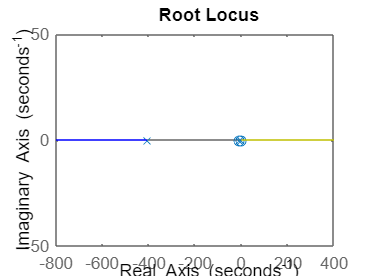

rlocus(Gel_pitSAS)

 A partir del grafico y por medio de iteraciones se llegan a los siguientes valores del controlador 

kiel_pit=-0.025;
kpel_pit=-0.125;
ncpit=[kpel_pit kiel_pit];dcpit=[1 0];
Cpit=tf(ncpit,dcpit)

Cpit =
 
  -0.125 s - 0.025
  ----------------
         s
 
Continuous-time transfer function.



Gel_pitCAS=feedback(Gel_pitSAS*Cpit,1)

Gel_pitCAS =
 
  From input to output "theta":
            16.76 s^5 + 237 s^4 + 897.6 s^3 + 453.7 s^2 + 56.71 s + 0.001991
  ------------------------------------------------------------------------------------
  s^7 + 421.4 s^6 + 5868 s^5 + 2.172e04 s^4 + 8158 s^3 + 1096 s^2 + 56.79 s + 0.001991
 
Continuous-time transfer function.



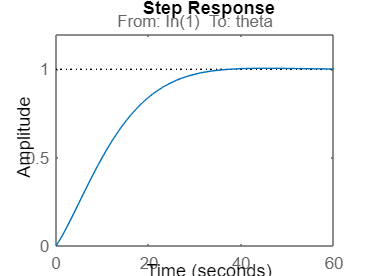

step(Gel_pitCAS)

stepinfo(Gel_pitCAS)

ans = struct with fields:
         RiseTime: 20.9166
    TransientTime: 31.2659
     SettlingTime: 31.2659
      SettlingMin: 0.9009
      SettlingMax: 1.0059
        Overshoot: 0.5908
       Undershoot: 0
             Peak: 1.0059
         PeakTime: 45.4601


**3.Eje Lateral / Direccional - Control PI+D**

%Nomenclatura Variables Eje Lateral/Direccional
%inputs: (8)Aileron ; (3) Ruddle
%Outputs: (5) phi-roll ; (8) roll rate-p ; (7)psi-ywa ; (10) yaw rater-r
lat=latmod 

lat =
 
  A = 
                 v           p           r         phi         psi
   v        -0.875      0.8751      -16.82       9.791           0
   p        -2.831      -16.14       3.377           0           0
   r         1.706      0.5154      -2.783           0           0
   phi           0           1     0.05385  -1.455e-24           0
   psi           0           0       1.001  -2.706e-23           0
 
  B = 
        aileron   rudder
   v          0    5.317
   p     -156.9   -5.022
   r      11.54   -82.27
   phi        0        0
   psi        0        0
 
  C = 
               v        p        r      phi      psi
   beta  0.05882        0        0        0        0
   p           0        1        0        0        0
   r           0        0        1        0        0
   phi         0        0        0        1        0
   psi         0        0        0        0        1
 
  D = 
         aileron   rudder
   beta        0        0
   p           0        0
   r      

lat.A(abs(lat.A)<1e-10)=0;
lat.B(abs(lat.B)<1e-10)=0;
lat.C(abs(lat.C)<1e-10)=0;
lat.D(abs(lat.D)<1e-10)=0;
latmodtf=tf(lat)

latmodtf =
 
  From input "aileron" to output...
                 -19.49 s^2 - 214.7 s - 225.8
   beta:  -------------------------------------------
          s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
          -156.9 s^3 - 535 s^2 - 4302 s + 123.9
   p:  -------------------------------------------
       s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
         11.54 s^3 + 115.4 s^2 - 113.6 s - 2302
   r:  -------------------------------------------
       s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
                 -156.3 s^2 - 528.8 s - 4308
   phi:  -------------------------------------------
         s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
             11.55 s^3 + 115.6 s^2 - 113.7 s - 2305
   psi:  -----------------------------------------------
         s^5 + 19.8 s^4 + 90.9 s^3 + 505.1 s^2 + 6.979 s
 
  From input "rudder" to output...
            0.3128 s^3 + 87.06 s^2 + 1309 s - 209.3
   beta:  -------------------------------------------
          s^4 + 19.8 s^3 + 90

**3.1 SAS**

**3.1.1 Aileron - Roll**

Gail_rol=latmodtf(4,1)

Gail_rol =
 
  From input "aileron" to output "phi":
          -156.3 s^2 - 528.8 s - 4308
  -------------------------------------------
  s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
Continuous-time transfer function.



Gail_p=latmodtf(2,1)

Gail_p =
 
  From input "aileron" to output "p":
     -156.9 s^3 - 535 s^2 - 4302 s + 123.9
  -------------------------------------------
  s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
Continuous-time transfer function.



Se obtiene la respuesta al impulso para cada  uno de las funciones de trasnferencia entre el Aileron y la posición y velocidad del ángulo Roll.

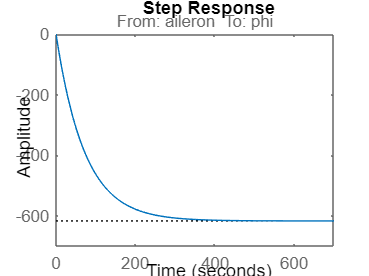

%Roll 
step(Gail_rol)

stepinfo(Gail_rol)

ans = struct with fields:
         RiseTime: 158.6096
    TransientTime: 282.4810
     SettlingTime: 282.4810
      SettlingMin: -617.2824
      SettlingMax: -558.3003
        Overshoot: 0
       Undershoot: 0
             Peak: 617.2824
         PeakTime: 761.3375


damp(Gail_rol)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.39e-02                 1.00e+00       1.39e-02         7.22e+01    
 -1.84e+00 + 5.28e+00i     3.29e-01       5.59e+00         5.43e-01    
 -1.84e+00 - 5.28e+00i     3.29e-01       5.59e+00         5.43e-01    
 -1.61e+01                 1.00e+00       1.61e+01         6.21e-02    


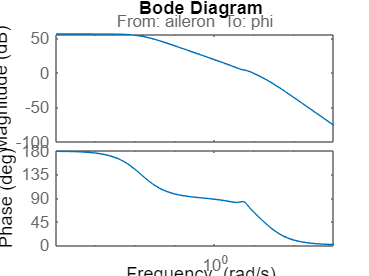

bode(Gail_rol)

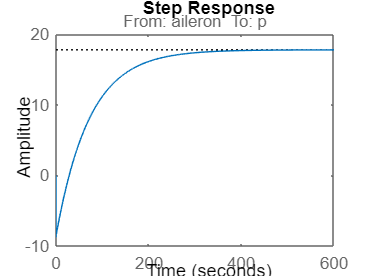

%Roll rate (p)
step(Gail_p)

stepinfo(Gail_p)

ans = struct with fields:
         RiseTime: 158.6246
    TransientTime: 281.9180
     SettlingTime: 310.9016
      SettlingMin: 15.9837
      SettlingMax: 17.7535
        Overshoot: 0
       Undershoot: 49.4024
             Peak: 17.7535
         PeakTime: 605.2001


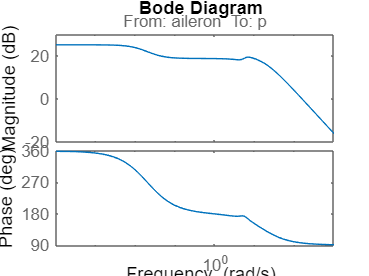

bode(Gail_p)

ail_p=ss(Gail_p);
damp(Gail_p)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.39e-02                 1.00e+00       1.39e-02         7.22e+01    
 -1.84e+00 + 5.28e+00i     3.29e-01       5.59e+00         5.43e-01    
 -1.84e+00 - 5.28e+00i     3.29e-01       5.59e+00         5.43e-01    
 -1.61e+01                 1.00e+00       1.61e+01         6.21e-02    


Para el diseño del sistema de aumento de estabilidad se analiza los polos de la función de transferencia de la velocidad respecto al aleron en lazo abierto.

***Ganancias Positivas***

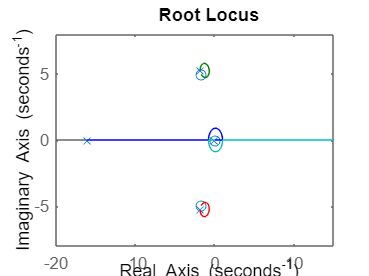

rlocus(Gail_p)

***Ganancias Negativas***

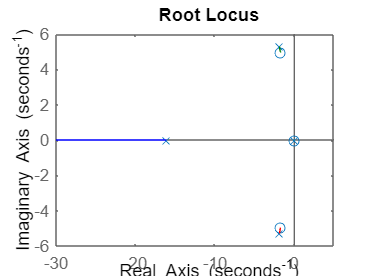

rlocus(-Gail_p)

Se pueded observar que la variación del amortiguamiento depende de la pareja de polos complejos conjugados ubicados 


$$p_{1,2} =-1\ldotp 84\pm 5\ldotp 28\;i$$


El valor absoluto de la constante de realimentación para el sistema SAS varia desde 0 hasta infinito inicialmente. De acuerdo al diagrama del lugar de las raices, el rango de las ganacias negativas para aumentar el amortiguamiento lo maximo posible son :


$$k=\left(-0\ldotp 0627\;,-0\ldotp 111\right)$$


Sin embargo, la presencia de un polo cercano a cero limita el valor de esta ganancia de realimentación. De acuerdo al mismo grafico, el valor minimo de la ganacia para la cual el polo se conserva en el lado izquierdo del plano-s (siendo estable ) es :


$$k=-0\ldotp 0561$$


Por ende este sera el valor que se usará para realizar la realimentación en el sistema SAS

kail_p=-0.05;
Gail_pSAS=feedback(Gail_p,kail_p)

Gail_pSAS =
 
  From input "aileron" to output "p":
      -156.9 s^3 - 535 s^2 - 4302 s + 123.9
  ----------------------------------------------
  s^4 + 27.64 s^3 + 117.7 s^2 + 720.2 s + 0.7818
 
Continuous-time transfer function.



damp(Gail_pSAS)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.09e-03                 1.00e+00       1.09e-03         9.21e+02    
 -1.83e+00 + 5.17e+00i     3.33e-01       5.48e+00         5.48e-01    
 -1.83e+00 - 5.17e+00i     3.33e-01       5.48e+00         5.48e-01    
 -2.40e+01                 1.00e+00       2.40e+01         4.17e-02    


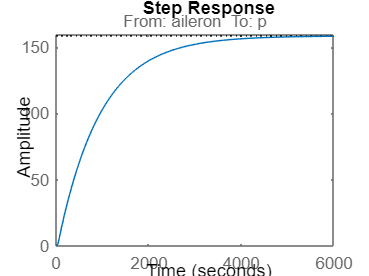

step(Gail_pSAS)

stepinfo(Gail_pSAS)

ans = struct with fields:
         RiseTime: 2.0238e+03
    TransientTime: 3.6375e+03
     SettlingTime: 3.6375e+03
      SettlingMin: 142.8234
      SettlingMax: 158.4281
        Overshoot: 0
       Undershoot: 0
             Peak: 158.4281
         PeakTime: 6.7440e+03


**3.1.2 Rudder - Yaw**

Grud_yaw=latmodtf(5,2)

Grud_yaw =
 
  From input "rudder" to output "psi":
       -82.39 s^3 - 1395 s^2 - 1238 s - 2368
  -----------------------------------------------
  s^5 + 19.8 s^4 + 90.9 s^3 + 505.1 s^2 + 6.979 s
 
Continuous-time transfer function.



Grud_r=latmodtf(3,2)

Grud_r =
 
  From input "rudder" to output "r":
     -82.27 s^3 - 1393 s^2 - 1237 s - 2365
  -------------------------------------------
  s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
Continuous-time transfer function.



Se obtiene la respuesta al impulso para cada  uno de las funciones de trasnferencia entre el Rudder y la posición y velocidad del ángulo Yaw.

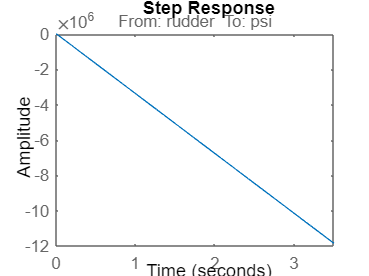

%Yaw
step(Grud_yaw)

stepinfo(Grud_yaw)

ans = struct with fields:
         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: NaN
       Undershoot: NaN
             Peak: Inf
         PeakTime: Inf


damp(Grud_yaw)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00                -1.00e+00       0.00e+00              Inf    
 -1.39e-02                 1.00e+00       1.39e-02         7.22e+01    
 -1.84e+00 + 5.28e+00i     3.29e-01       5.59e+00         5.43e-01    
 -1.84e+00 - 5.28e+00i     3.29e-01       5.59e+00         5.43e-01    
 -1.61e+01                 1.00e+00       1.61e+01         6.21e-02    


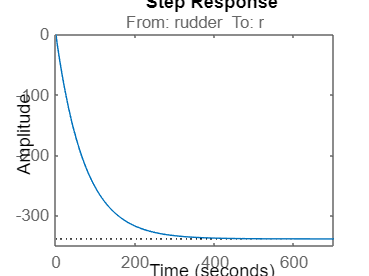

%Yaw Rate
step(Grud_r)

stepinfo(Grud_r)

ans = struct with fields:
         RiseTime: 158.6198
    TransientTime: 282.0940
     SettlingTime: 282.0940
      SettlingMin: -338.8252
      SettlingMax: -305.1086
        Overshoot: 0
       Undershoot: 0
             Peak: 338.8252
         PeakTime: 761.3375


damp(Grud_r)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.39e-02                 1.00e+00       1.39e-02         7.22e+01    
 -1.84e+00 + 5.28e+00i     3.29e-01       5.59e+00         5.43e-01    
 -1.84e+00 - 5.28e+00i     3.29e-01       5.59e+00         5.43e-01    
 -1.61e+01                 1.00e+00       1.61e+01         6.21e-02    


Para el diseño del sistema de aumento de estabilidad se analiza los polos de la función de transferencia de la velocidad respecto al aleron en lazo abierto.

***Ganancias Positivas***

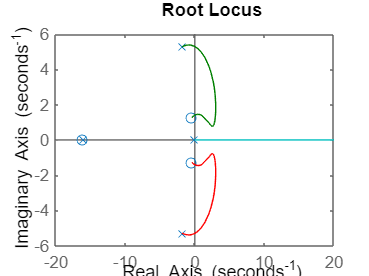

rlocus(Grud_r)

***Ganancias Negativas***

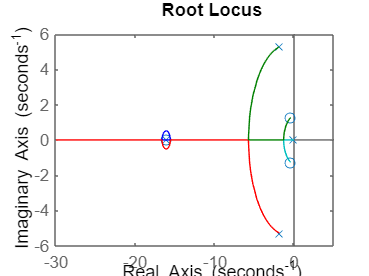

rlocus(-Grud_r)

-0,17

krud_r=-0.17;
Grud_rSAS=feedback(Grud_r,krud_r)

Grud_rSAS =
 
  From input "rudder" to output "r":
     -82.27 s^3 - 1393 s^2 - 1237 s - 2365
  -------------------------------------------
  s^4 + 33.78 s^3 + 327.8 s^2 + 715.3 s + 409
 
Continuous-time transfer function.



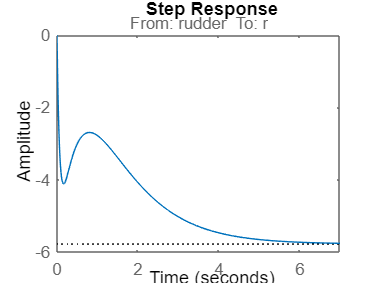

step(Grud_rSAS)

stepinfo(Grud_rSAS)

ans = struct with fields:
         RiseTime: 3.2969
    TransientTime: 5.0765
     SettlingTime: 5.0765
      SettlingMin: -5.7738
      SettlingMax: -5.2064
        Overshoot: 0
       Undershoot: 0
             Peak: 5.7738
         PeakTime: 7.9186


damp(Grud_rSAS)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -9.34e-01     1.00e+00       9.34e-01         1.07e+00    
 -1.82e+00     1.00e+00       1.82e+00         5.50e-01    
 -1.52e+01     1.00e+00       1.52e+01         6.57e-02    
 -1.58e+01     1.00e+00       1.58e+01         6.33e-02    


**3.2 CAS**

Para el diseño de sistema de aumento de Control se genera un sistema acoplado a partir de los controladores SAS diseñados anteriormente.

lat

lat =
 
  A = 
              v        p        r      phi      psi
   v     -0.875   0.8751   -16.82    9.791        0
   p     -2.831   -16.14    3.377        0        0
   r      1.706   0.5154   -2.783        0        0
   phi        0        1  0.05385        0        0
   psi        0        0    1.001        0        0
 
  B = 
        aileron   rudder
   v          0    5.317
   p     -156.9   -5.022
   r      11.54   -82.27
   phi        0        0
   psi        0        0
 
  C = 
               v        p        r      phi      psi
   beta  0.05882        0        0        0        0
   p           0        1        0        0        0
   r           0        0        1        0        0
   phi         0        0        0        1        0
   psi         0        0        0        0        1
 
  D = 
         aileron   rudder
   beta        0        0
   p           0        0
   r           0        0
   phi         0        0
   psi         0        0
 
Continuous-time stat

latmodtf;
laux=latmodtf;
sas=ss(latmodtf)

sas =
 
  A = 
             x1       x2       x3       x4       x5       x6       x7       x8       x9      x10
   x1         0        0        0  -0.4362        0        0        0        0        0        0
   x2      0.25        0        0   -7.892        0        0        0        0        0        0
   x3         0        8        0   -11.36        0        0        0        0        0        0
   x4         0        0        8    -19.8        0        0        0        0        0        0
   x5         0        0        0        0        0        0        0  -0.4362        0        0
   x6         0        0        0        0     0.25        0        0   -7.892        0        0
   x7         0        0        0        0        0        8        0   -11.36        0        0
   x8         0        0        0        0        0        0        8    -19.8        0        0
   x9         0        0        0        0        0        0        0        0        0        0
   x10        0

size(lat)

State-space model with 5 outputs, 2 inputs, and 5 states.


size(sas)

State-space model with 5 outputs, 2 inputs, and 21 states.


devk=[kail_p 0 ; 0 krud_r];
feedin=[1 2];
feedout=[2 3];
SASfeedtf=feedback(lat,devk,feedin,feedout)

SASfeedtf =
 
  A = 
              v        p        r      phi      psi
   v     -0.875   0.8751   -15.92    9.791        0
   p     -2.831   -23.98    2.523        0        0
   r      1.706    1.092   -16.77        0        0
   phi        0        1  0.05385        0        0
   psi        0        0    1.001        0        0
 
  B = 
        aileron   rudder
   v          0    5.317
   p     -156.9   -5.022
   r      11.54   -82.27
   phi        0        0
   psi        0        0
 
  C = 
               v        p        r      phi      psi
   beta  0.05882        0        0        0        0
   p           0        1        0        0        0
   r           0        0        1        0        0
   phi         0        0        0        1        0
   psi         0        0        0        0        1
 
  D = 
         aileron   rudder
   beta        0        0
   p           0        0
   r           0        0
   phi         0        0
   psi         0        0
 
Continuous-tim

SASfeedtf2=feedback(sas,devk,feedin,feedout)

SASfeedtf2 =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9
   x1          0         0         0   -0.4362         0         0         0    -2.822         0
   x2       0.25         0         0    -7.892         0         0         0   -0.6709         0
   x3          0         8         0    -11.36         0         0         0   -0.4873         0
   x4          0         0         8     -19.8         0         0         0         0         0
   x5          0         0         0         0         0         0         0  -0.04886         0
   x6          0         0         0         0      0.25         0         0    -11.25         0
   x7          0         0         0         0         0         8         0    -14.71         0
   x8          0         0         0         0         0         0         8    -27.64         0
   x9          0         0         0         0         0         0         0    -7.193         0
   x10  

G11=tf(SASfeedtf2)

G11 =
 
  From input "aileron" to output...
                                                                                                 
            -18.88 s^10 - 1070 s^9 - 2.51e04 s^8 - 3.313e05 s^7 - 2.878e06 s^6 - 1.775e07 s^5    
                                                                                                 
                             - 7.683e07 s^4 - 2.206e08 s^3 - 3.857e08 s^2 - 1.056e07 s - 7.283e04
                                                                                                 
   beta:  -----------------------------------------------------------------------------------------
                                                                                                   
          s^12 + 81.22 s^11 + 2687 s^10 + 4.791e04 s^9 + 5.274e05 s^8 + 4.01e06 s^7 + 2.215e07 s^6 
                                                                                                   
                  + 8.407e07 s^5 + 2.244e08 s^4 + 3.009e08 s^3 + 1

G22=tf(SASfeedtf)

G22 =
 
  From input "aileron" to output...
                  -18.88 s^2 - 322.6 s - 1495
   beta:  --------------------------------------------
          s^4 + 41.63 s^3 + 464.7 s^2 + 1016 s + 402.8
 
          -156.9 s^3 - 2739 s^2 - 6018 s + 123.9
   p:  --------------------------------------------
       s^4 + 41.63 s^3 + 464.7 s^2 + 1016 s + 402.8
 
          11.54 s^3 + 115.4 s^2 - 113.6 s - 2302
   r:  --------------------------------------------
       s^4 + 41.63 s^3 + 464.7 s^2 + 1016 s + 402.8
 
                  -156.3 s^2 - 2733 s - 6024
   phi:  --------------------------------------------
         s^4 + 41.63 s^3 + 464.7 s^2 + 1016 s + 402.8
 
              11.55 s^3 + 115.6 s^2 - 113.7 s - 2305
   psi:  ------------------------------------------------
         s^5 + 41.63 s^4 + 464.7 s^3 + 1016 s^2 + 402.8 s
 
  From input "rudder" to output...
            0.3128 s^3 + 89.51 s^2 + 1957 s - 229.4
   beta:  --------------------------------------------
          s^4 + 41.6


Gail_rolSASf=tf(G22(4,1))

Gail_rolSASf =
 
  From input "aileron" to output "phi":
           -156.3 s^2 - 2733 s - 6024
  --------------------------------------------
  s^4 + 41.63 s^3 + 464.7 s^2 + 1016 s + 402.8
 
Continuous-time transfer function.



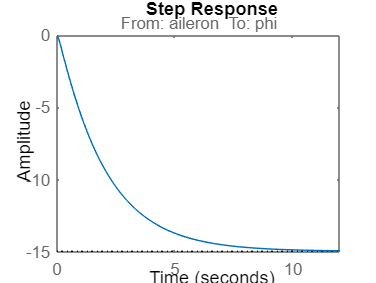

step(Gail_rolSASf)

stepinfo(Gail_rolSASf)

ans = struct with fields:
         RiseTime: 4.3665
    TransientTime: 7.7999
     SettlingTime: 7.7999
      SettlingMin: -14.9467
      SettlingMax: -13.5022
        Overshoot: 0
       Undershoot: 0
             Peak: 14.9467
         PeakTime: 14.3614


kpail_rol=-0.08;
kiail_rol=-0.03;
nr=[kpail_rol  kiail_rol];dr=[1 0];
Croll=tf(nr,dr);
Gail_rolCAS=feedback(Croll*Gail_rolSASf,1)

Gail_rolCAS =
 
  From input "aileron" to output:
           12.5 s^3 + 223.3 s^2 + 563.9 s + 180.7
  --------------------------------------------------------
  s^5 + 41.63 s^4 + 477.2 s^3 + 1240 s^2 + 966.7 s + 180.7
 
Continuous-time transfer function.



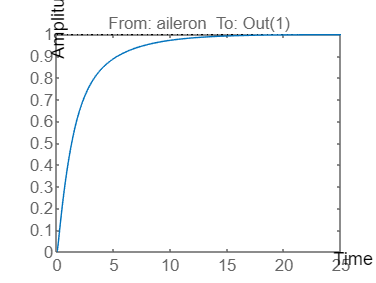

step(Gail_rolCAS)

stepinfo(Gail_rolCAS)

ans = struct with fields:
         RiseTime: 5.0979
    TransientTime: 11.0505
     SettlingTime: 11.0505
      SettlingMin: 0.9010
      SettlingMax: 0.9995
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9995
         PeakTime: 24.3059




Grud_yawSASf=tf(G22(5,2))

Grud_yawSASf =
 
  From input "rudder" to output "psi":
       -82.39 s^3 - 2045 s^2 - 1744 s - 2368
  ------------------------------------------------
  s^5 + 41.63 s^4 + 464.7 s^3 + 1016 s^2 + 402.8 s
 
Continuous-time transfer function.



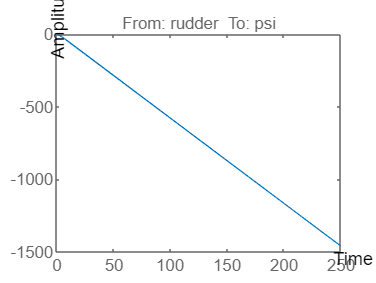

step(Grud_yawSASf)

stepinfo(Grud_yawSASf)

ans = struct with fields:
         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: NaN
       Undershoot: NaN
             Peak: Inf
         PeakTime: Inf


kprud_yaw=-0.05;
kirud_yaw=-0.0001;
ny=[kprud_yaw kirud_yaw];dy=[1 0];
Cyaw=tf(ny,dy)

Cyaw =
 
  -0.05 s - 0.0001
  ----------------
         s
 
Continuous-time transfer function.



Grud_yawCAS=feedback(Cyaw*Grud_yawSASf,1)

Grud_yawCAS =
 
  From input "rudder" to output:
           4.12 s^4 + 102.2 s^3 + 87.41 s^2 + 118.6 s + 0.2368
  ---------------------------------------------------------------------
  s^6 + 41.63 s^5 + 468.8 s^4 + 1118 s^3 + 490.2 s^2 + 118.6 s + 0.2368
 
Continuous-time transfer function.



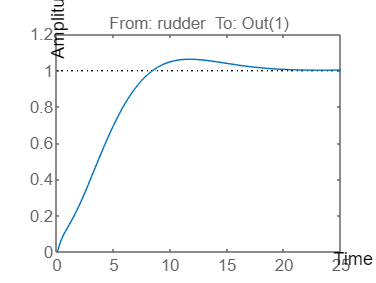

step(Grud_yawCAS)

stepinfo(Grud_yawCAS)

ans = struct with fields:
         RiseTime: 6.2243
    TransientTime: 17.3511
     SettlingTime: 17.3511
      SettlingMin: 0.9029
      SettlingMax: 1.0631
        Overshoot: 6.3143
       Undershoot: 0
             Peak: 1.0631
         PeakTime: 11.7106
